# Create Deep Learning Network Architecture

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable `layers`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 09-May-2024 21:04:43

## Create Array of Layers

layers = [
    imageInputLayer([227 227 3],"Name","imageinput")
    convolution2dLayer([3 3],32,"Name","conv","Padding","same")
    reluLayer("Name","relu")
    maxPooling2dLayer([5 5],"Name","maxpool","Padding","same")
    convolution2dLayer([3 3],32,"Name","conv_1","Padding","same")
    reluLayer("Name","relu_1")
    fullyConnectedLayer(3,"Name","fc")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];

## Plot Layers

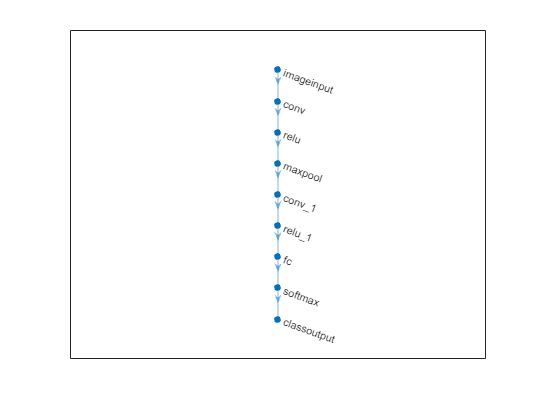

plot(layerGraph(layers));

## Define Input & Training Parameters

imds = imageDatastore('C:\Users\user\Desktop\Github Projects\matlab-deep-learning-designer\data', ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');

options = trainingOptions('adam', ...
    'MiniBatchSize',128, ...
    'MaxEpoch',20, ...
    'ValidationFrequency',5, ...
    'InitialLearnRate',1e-4,'Plots','training-progress');

## Network Training

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |       53.33% |       6.9109 |      1.0000e-04 |
|      20 |          20 |       00:00:03 |      100.00% |   0.0000e+00 |      1.0000e-04 |
|========================================================================================|
Training finished: Max epochs completed.


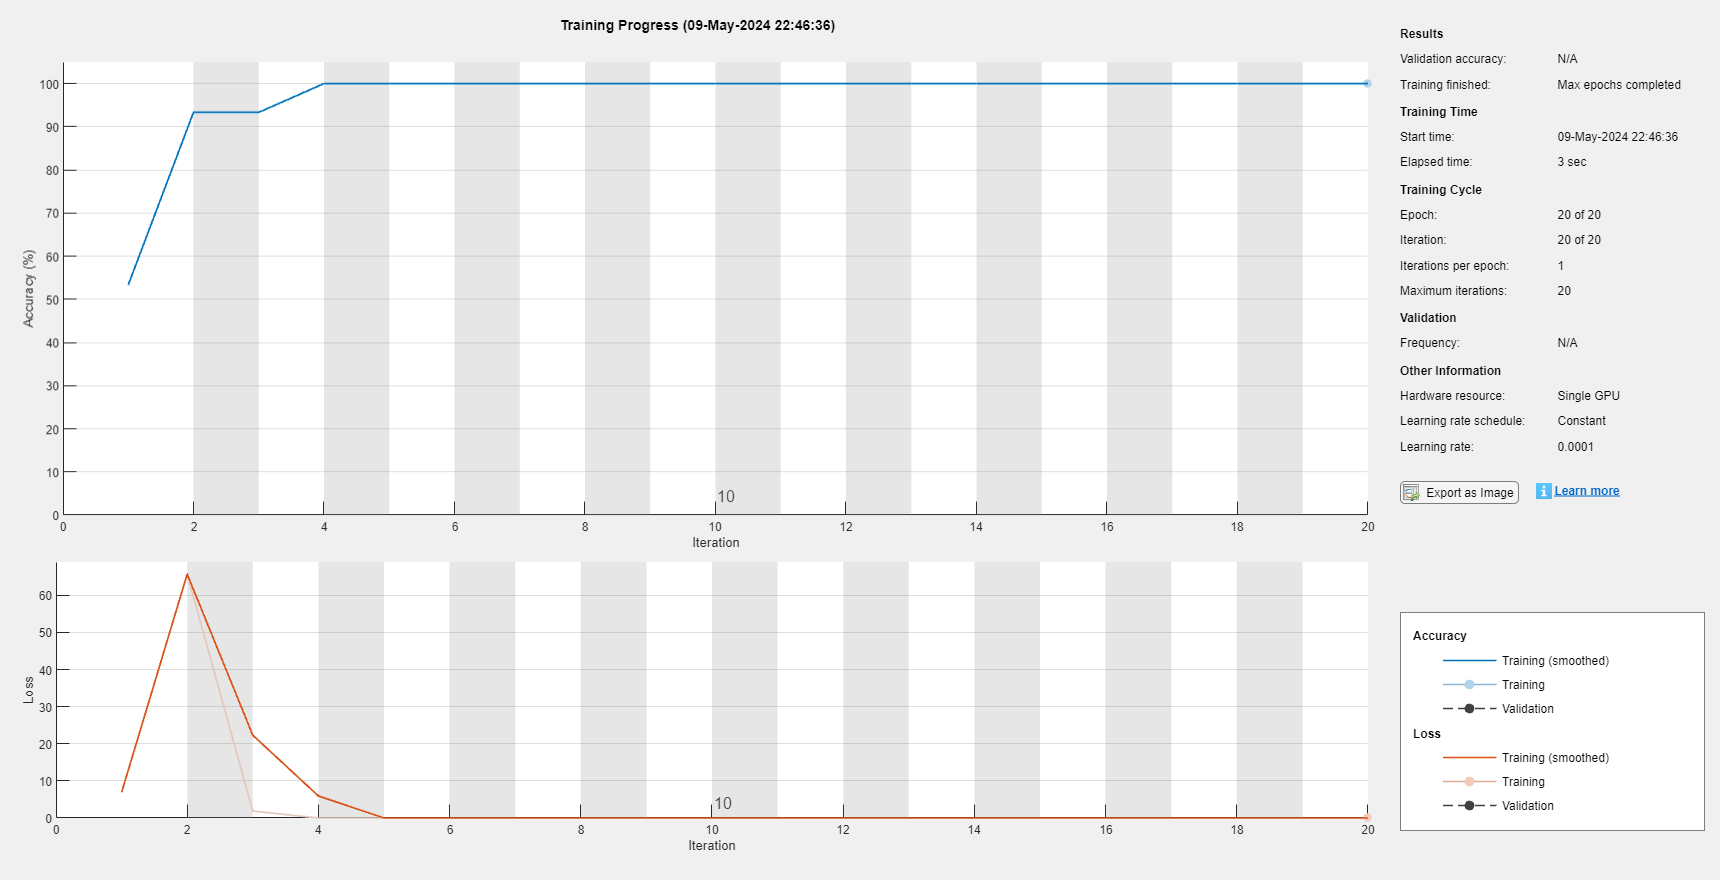

[convnet, traininfo] = trainNetwork(imds, layers, options);


inp = 'forest.jpg'

inp = 'forest.jpg'

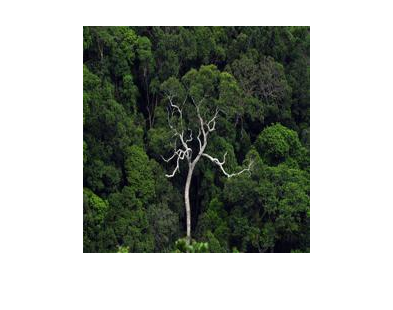

I = imread(inp);
figure, imshow(I)

## Classification

class = classify(convnet, I)

class = categorical
     forest 


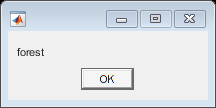

msgbox(char(class))